# **LQR线性二次型调节器（Linear Quadratic Regulator）**

**本文档从系统稳定性出发，引出LQR线性二次型调节器来优化极点配置以达到不同的控制效果**

# **一、状态空间方程与开环稳定性 (Open-Loop Analysis)**

### ***1. 开环系统稳定性判据***

对于线性时不变系统 (LTI)，可有以下的状态方程：

###  
$$$ \dot{x}(t) = Ax(t) + Bu(t) $$$


开环系统（**令u=0/u与x无关**）的稳定性完全取决于矩阵 A 的特征值 (Eigenvalues)。 特征方程为： 

### 
$$$ \det(\lambda I - A) = 0 $$$
 

根 $\lambda$ 即为系统的极点。我们可以很轻松在matlab判断系统的稳定性：

disp(' ');

disp('=== 开环系统稳定性判据 ===');

=== 开环系统稳定性判据 ===


% 定义一个抽象的二阶不稳定系统
A = [0,  1; 
     2,  0];  % 这里的 '2' 导致特征值会出现正实部，系统不稳定
B = [0; 
     1];
C = [1, 0];   % 假设观测 x1
D = 0;

disp('=== 1. 开环系统分析 ===');

=== 1. 开环系统分析 ===


disp('系统矩阵 A:'); disp(A);

系统矩阵 A:
     0     1
     2     0



% 特征值计算 
open_loop_poles = eig(A);

disp('开环特征值 (Open-loop Eigenvalues):');

开环特征值 (Open-loop Eigenvalues):


disp(open_loop_poles);

    1.4142
   -1.4142



% 稳定性判定：存在大于零的实部即说明系统不稳定
if any(real(open_loop_poles) > 0)
    disp('结论: 存在实部为正的特征值 -> 系统不稳定 (Unstable)。');
else
    disp('结论: 系统稳定。');
end

结论: 存在实部为正的特征值 -> 系统不稳定 (Unstable)。


### ***2. 闭环系统稳定性判据***

接下来我们采用全状态反馈控制律： 

### 
$$u = -Kx$$


此时系统成为一个闭环系统，x就是我们的被控量。代入原方程：

###  
$$$ \dot{x} = Ax + B(-Kx) = (A - BK)x $$$


此时我们得到新的闭环系统矩阵：

###  
$$$ A_{cl} = A - BK $$$


 我们的目标是选择 K，使得 $A_{cl}$ 的所有特征值都在复平面左半平面（实部都＜0）。

disp(' ');

disp('=== 极点配置 (Pole Placement) 的数学局限 ===');

=== 极点配置 (Pole Placement) 的数学局限 ===



% 认为选定极点后求解K矩阵
desired_poles = [-2, -3];% 我们随意指定两个稳定极点：p1 = -2, p2 = -3
K_place = place(A, B, desired_poles);

% 验证闭环矩阵
A_cl_place = A - B * K_place;
calculated_poles = eig(A_cl_place);

disp('手动配置极点 [-2, -3] 对应的增益 K:'); disp(K_place);

手动配置极点 [-2, -3] 对应的增益 K:
    8.0000    5.0000



disp('闭环矩阵 (A - BK) 的特征值:'); disp(calculated_poles);

闭环矩阵 (A - BK) 的特征值:
   -2.0000
   -3.0000




% 稳定性判定：存在大于零的实部即说明系统不稳定
if any(real(calculated_poles) > 0)
    disp('结论: 存在实部为正的特征值 -> 系统不稳定 (Unstable)。');
else
    disp('结论: 系统稳定。');
end

结论: 系统稳定。


虽然数学上我们可以把极点配置到任意位置（只要系统可控），但为什么选 [-2, -3]？为什么不选 [-10, -20]？

极点选得越负，收敛越快，但 K 值（以及控制能量 u）会呈指数级增长。单纯的特征值分析无法告诉我们要付出多少代价。因此我们需要一种手段可以优化/量化我们的极点配置，这是我们引入LQR的原因

# **二、LQR 的引入与黎卡提方程 (LQR & Riccati Equation)**

### ***1.代价函数***

LQR 将“选极点”问题转化为“泛函极值”问题，通过定义“**代价函数**” (Cost Function) J：

### 
$$ J = \int_{0}^{\infty} ( \underbrace{x^T Q x}_{\text{误差惩罚}} + \underbrace{u^T R u}_{\text{能量惩罚}} ) dt $$


可以看出，Q矩阵越大，误差带来的Penalty越大（控不住/收敛不了）；R矩阵越大，输入带来的Penalty越大（大力气办小事情）

- **Q (状态权重矩阵)***：描述你对误差的容忍度。 - Q 里面的元素越大，代表你越容忍不了这个状态有误差。 - LQR 就会拼命去消除这个状态的误差（反应变快）

- **R (控制权重矩阵)***：描述你对能量消耗的吝啬程度。 - R 越大，代表你越心疼电费（或者电机力矩有限）。 - LQR 就会限制输出电压 $u$ 的幅度（反应变慢，但动作更省力）

而我们的目标是：找到一个K矩阵，使得 J 最小

### *2. 黎卡提方程 (Riccati Equation)*

根据庞特里亚金最小值原理，最优解依赖于 代数黎卡提方程 (ARE)： 

### 
$$$ A^T P + P A - P B R^{-1} B^T P + Q = 0 $$$


其中 P 是唯一的对称正定解矩阵。由此我么可以得到最优反馈增益K，也就得到了最优的极点配置来更新我们的输入矩阵$$u$$，实现LQR闭环控制

###  
$$$ K_{lqr} = R^{-1} B^T P $$$


我们可以在matlab中很轻松的求解K矩阵的数值解，并代入黎卡提方程进行检验

disp(' ');

disp('=== LQR 推导与黎卡提方程验证 ===');

=== LQR 推导与黎卡提方程验证 ===



% 定义权重矩阵
Q = [10, 0;  % 惩罚 x1 的偏差
     0,  1]; % x2 的偏差不太重要
R = 1;       % 惩罚控制量 u

disp('权重矩阵 Q:'); disp(Q);

权重矩阵 Q:
    10     0
     0     1



disp('权重系数 R:'); disp(R);

权重系数 R:
     1




% 求解K矩阵
[K_lqr, P_sol, E_lqr] = lqr(A, B, Q, R);

disp('LQR 计算出的最优增益 K:'); disp(K_lqr);

LQR 计算出的最优增益 K:
    5.7417    3.5332



disp('黎卡提方程的解矩阵 P:'); disp(P_sol);

黎卡提方程的解矩阵 P:
   13.2199    5.7417
    5.7417    3.5332



disp('LQR 自动选择的闭环特征值 (Closed-loop Poles):'); disp(E_lqr);

LQR 自动选择的闭环特征值 (Closed-loop Poles):
  -1.7666 + 0.7879i
  -1.7666 - 0.7879i




% --- B. 数学验证：手动代入黎卡提方程 ---
% 验证: A'P + PA - PBR^-1B'P + Q 应该等于 0 矩阵
ARE_residual = A' * P_sol + P_sol * A - P_sol * B * inv(R) * B' * P_sol + Q;

disp('验证黎卡提方程 (结果应接近全0矩阵):');

验证黎卡提方程 (结果应接近全0矩阵):


disp(ARE_residual);

   1.0e-13 *

    0.2842    0.1066
    0.1066    0.0355




% 寻找数值解即可 ARE_residual ≈ 0
if norm(ARE_residual) < 1e-10
    disp('✅ 黎卡提方程验证通过：数学推导成立。');
else
    disp('❌ 验证失败。');
end

✅ 黎卡提方程验证通过：数学推导成立。


到这里，我们成功地优化了我们的极点配置，找到了收敛速度与能耗输出的平衡点。

# **三、经典倒立摆下的LQR控制**

这是一个经典的4阶倒立摆系统，非常适合演示 LQR 如何协调多个状态。

状态向量 x = [小车位移; 小车速度; 摆杆角度; 摆杆角速度] 

控制输入 u = 小车电机的推力

### ***1.全状态反馈下的系统可控性Controllability分析***

全状态反馈下的系统转移矩阵的秩揭示了系统的可控性***Controllability***，即：

### 
$$$ Rank(A_{cl}) = Rank(A - BK) = Rank(x) $$$


如果上式成立，则系统一定可控（一定有合适的极点配置可以完成控制量收敛），反之则无

disp(' ');

disp('=== 全状态反馈下的系统可控性Controllability分析 ===');

=== 全状态反馈下的系统可控性Controllability分析 ===


% 物理参数
M = 1.0;  % 小车质量 (kg)
m = 0.1;  % 摆杆质量 (kg)
l = 0.5;  % 摆杆长度 (m)
g = 9.8;  % 重力

% 线性化后的系统矩阵 (推导过程略，直接给出结果)
% x1=位移, x2=速度, x3=角度(垂直向上为0), x4=角速度
A = [0, 1,    0,       0;
     0, 0,  -m*g/M,    0;  % 简化模型
     0, 0,    0,       1;
     0, 0, (M+m)*g/(M*l), 0];

B = [0; 
     1/M; 
     0; 
     -1/(M*l)];

C = eye(4); % 假定所有状态都能测到 (全状态反馈)
D = 0;

sys = ss(A, B, C, D);

% 检查可控性 (Controllability)
% 如果 rank(Co) < 4，系统不可控，LQR 也没救
Co = ctrb(A, B);
if rank(Co) == 4 
    disp('✅ 系统是完全可控的，可以设计 LQR。');
else
    error('❌ 系统不可控！');
end

✅ 系统是完全可控的，可以设计 LQR。


### ***2. 设计三组不同的Q与R***

我们设计三组 Q 和 R，看看它们对系统行为的影响。

disp(' ');

disp('=== 设计三组不同的Q与R ===');

=== 设计三组不同的Q与R ===


% --- 方案 A: 均衡型 (默认) ---
% 我们只关心角度 x3 (希望能平衡) 和 位移 x1 (希望能回到原点)
Q_A = diag([10, 0, 100, 0]); % 角度权重100(最重要)，位移权重10
R_A = 1;                     % 能量权重 1
K_A = lqr(A, B, Q_A, R_A);

% --- 方案 B: 激进型 (不在乎能量，只要稳得快) ---
% R 很小，意味着电费不要钱，电机尽管通过最大电流
Q_B = Q_A;      % 权重不变
R_B = 0.01;     % 能量权重极小
K_B = lqr(A, B, Q_B, R_B);

% --- 方案 C: 吝啬型 (电池快没电了) ---
% R 很大，意味着动作要非常轻柔
Q_C = Q_A;      
R_C = 100;      % 能量权重极大
K_C = lqr(A, B, Q_C, R_C);

% 打印增益矩阵 K 看看区别
fprintf('\n--- 反馈增益 K 对比 ---\n');


--- 反馈增益 K 对比 ---


fprintf('A (均衡): [%.2f, %.2f, %.2f, %.2f]\n', K_A);

A (均衡): [-3.16, -4.25, -38.72, -8.22]


fprintf('B (激进): [%.2f, %.2f, %.2f, %.2f] -> 增益巨大！\n', K_B);

B (激进): [-31.62, -30.82, -157.96, -27.33] -> 增益巨大！


fprintf('C (吝啬): [%.2f, %.2f, %.2f, %.2f] -> 增益很小\n', K_C);

C (吝啬): [-0.32, -0.97, -25.43, -5.51] -> 增益很小


### *3.仿真对比*

初始状态：杆子歪了 0.2 rad，小车在原点

x0 = [0; 0; 0.2; 0]; 

% 构建全状态反馈下的状态空间方程: dx = (A - BK)x
sys_cl_A = ss(A - B*K_A, zeros(4,1), C, 0);
sys_cl_B = ss(A - B*K_B, zeros(4,1), C, 0);
sys_cl_C = ss(A - B*K_C, zeros(4,1), C, 0);

t = 0:0.01:5;
[y_A, t, x_A] = initial(sys_cl_A, x0, t);
[y_B, t, x_B] = initial(sys_cl_B, x0, t);
[y_C, t, x_C] = initial(sys_cl_C, x0, t);

% 计算控制输入 u = -Kx
u_A = -x_A * K_A'; u_A = u_A(:,1); % 实际上 u 是一维的
u_B = -x_B * K_B'; u_B = u_B(:,1);
u_C = -x_C * K_C'; u_C = u_C(:,1);

### *4. 绘图分析*

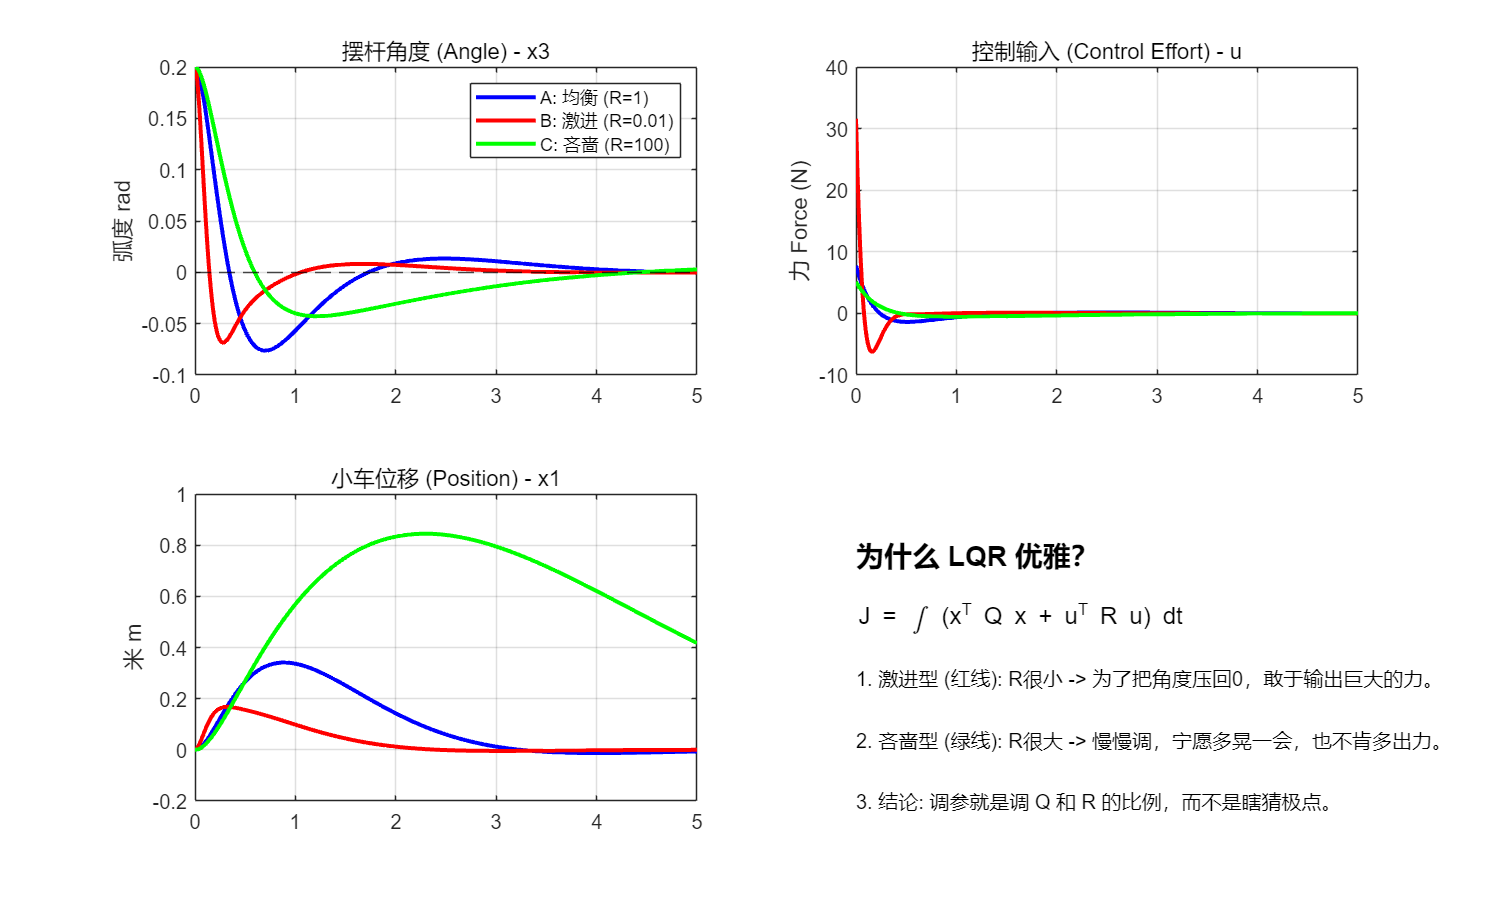

figure('Color', 'w', 'Position', [100, 100, 1000, 600]);

% 子图1：角度响应 (我们最关心的)
subplot(2, 2, 1);
plot(t, x_A(:,3), 'b', 'LineWidth', 2); hold on;
plot(t, x_B(:,3), 'r', 'LineWidth', 2);
plot(t, x_C(:,3), 'g', 'LineWidth', 2);
yline(0, 'k--');
title('摆杆角度 (Angle) - x3');
legend('A: 均衡 (R=1)', 'B: 激进 (R=0.01)', 'C: 吝啬 (R=100)');
ylabel('弧度 rad'); grid on;

% 子图2：控制输入 (电压/力)
subplot(2, 2, 2);
plot(t, u_A, 'b', 'LineWidth', 2); hold on;
plot(t, u_B, 'r', 'LineWidth', 2);
plot(t, u_C, 'g', 'LineWidth', 2);
title('控制输入 (Control Effort) - u');
ylabel('力 Force (N)'); grid on;
% 注意看红色线(B)的初始值非常大！

% 子图3：小车位移
subplot(2, 2, 3);
plot(t, x_A(:,1), 'b', 'LineWidth', 2); hold on;
plot(t, x_B(:,1), 'r', 'LineWidth', 2);
plot(t, x_C(:,1), 'g', 'LineWidth', 2);
title('小车位移 (Position) - x1');
ylabel('米 m'); grid on;
% 吝啬型(C)为了省力，可能会让小车漂移得更远才回来

% 子图4：代价函数 J 的物理意义示意
subplot(2, 2, 4);
axis off;
text(0, 0.8, '为什么 LQR 优雅？', 'FontSize', 14, 'FontWeight', 'bold');
text(0, 0.6, 'J = \int (x^T Q x + u^T R u) dt', 'FontSize', 12);
text(0, 0.4, '1. 激进型 (红线): R很小 -> 为了把角度压回0，敢于输出巨大的力。');
text(0, 0.2, '2. 吝啬型 (绿线): R很大 -> 慢慢调，宁愿多晃一会，也不肯多出力。');
text(0, 0,   '3. 结论: 调参就是调 Q 和 R 的比例，而不是瞎猜极点。');

# **四、Summary**

***1.状态空间方程不仅描述了系统，还通过特征值揭示了稳定性***

***2. 我们可以通过 K 任意改变特征值（极点配置），但这缺乏理论指导***

***3. LQR 通过解黎卡提方程 (A'P + PA - PBR^-1B'P + Q = 0)，在数学上 找到了一个平衡点：最优K矩阵，它自动确定当前约束下最佳闭环特征值的位置，这就是它的物理意义***

- LQR 的本质是解一个 "Riccati 方程" (MATLAB 的 lqr 函数自动完成)。

- Q 矩阵：对角线元素 Q(i,i) 越大，表示你越希望第 i 个状态 x(i) 快速归零。

- R 矩阵：R 越大，控制越保守；R 越小，控制越暴力。

- 实际工程中，我们通常把 R 固定为 1，然后去调整 Q 里面的元素，直到满意为止。

***4.进行 LQR 之前我们还可以通过确定全反馈下状态转移矩阵的秩来判断系统可控性Controllability***

***笔者：卢俊烨***

#### ***日期：2025.12.02***

***https://github.com/yagami-light7***